# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 22-Nov-2020 22:06:22

## Load the Pretrained Parameters

params = load("/home/basia/Documents/Filtry/params_2020_11_22__22_06_14.mat");

## Create Array of Layers

layers = [
    imageInputLayer([224 224 3],"Name","input","Mean",params.input.Mean)
    convolution2dLayer([3 3],64,"Name","conv1_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv1_1.Bias,"Weights",params.conv1_1.Weights)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],64,"Name","conv1_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv1_2.Bias,"Weights",params.conv1_2.Weights)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv2_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv2_1.Bias,"Weights",params.conv2_1.Weights)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],128,"Name","conv2_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv2_2.Bias,"Weights",params.conv2_2.Weights)
    reluLayer("Name","re" + ...
    "lu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv3_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv3_1.Bias,"Weights",params.conv3_1.Weights)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],256,"Name","conv3_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv3_2.Bias,"Weights",params.conv3_2.Weights)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],256,"Name","conv3_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv3_3.Bias,"Weights",params.conv3_3.Weights)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv4_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv4_1.Bias,"Weights",params.conv4_1.Weights)
    reluLayer("Name","relu4_1")
    convolution2dLayer([3 3],512,"Name","conv4_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv4_2.Bias,"Weights",params.conv4_2.Weights)
    reluLayer("Name","relu4_2")
    convolution2dLayer([3 3],512,"Name","conv4_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv4_3.Bias,"Weights",params.conv4_3.Weights)
    reluLayer("Name","relu4_3")
    maxPooling2dLayer([2 2],"Name","pool4","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv5_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv5_1.Bias,"Weights",params.conv5_1.Weights)
    reluLayer("Name","relu5_1")
    convolution2dLayer([3 3],512,"Name","conv5_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv5_2.Bias,"Weights",params.conv5_2.Weights)
    reluLayer("Name","relu5_2")
    convolution2dLayer([3 3],512,"Name","conv5_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv5_3.Bias,"Weights",params.conv5_3.Weights)
    reluLayer("Name","relu5_3")
    maxPooling2dLayer([2 2],"Name","pool5","Stride",[2 2])
    globalAveragePooling2dLayer("Name","gapool")
    dropoutLayer(0.2,"Name","dropout_1")
    batchNormalizationLayer("Name","batchnorm")
    fullyConnectedLayer(4096,"Name","fc_1")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(4096,"Name","fc_2")
    reluLayer("Name","relu_2")
    dropoutLayer(0.2,"Name","dropout_2")
    fullyConnectedLayer(6,"Name","fc_3")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot Layer

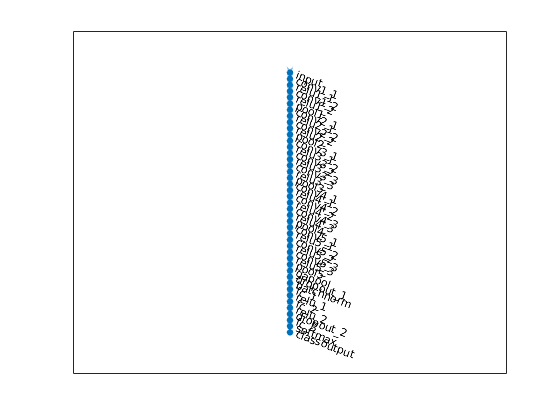

plot(layerGraph(layers));

## Import Data

data = imageDatastore('/home/basia/Documents/Filtry/titan/', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');
imageSize = layers(1).InputSize;
%data.ReadFcn = @(data)imresize(imread(data),imageSize);
[trainingSet, testSet] = splitEachLabel(data, 0.2);
auimdsTrain = augmentedImageDatastore(imageSize,trainingSet,'ColorPreprocessing','gray2rgb');
auimdsTest = augmentedImageDatastore(imageSize,testSet,'ColorPreprocessing','gray2rgb');

auimdsTrain.preview()

ans = 8×2 table
          input          response
    _________________    ________

    {224×224×3 uint8}      AML   
    {224×224×3 uint8}      AML   
    {224×224×3 uint8}      AML   
    {224×224×3 uint8}      AML   
    {224×224×3 uint8}      AML   
    {224×224×3 uint8}      AML   
    {224×224×3 uint8}      AML   
    {224×224×3 uint8}      AML   


## Training Options

options = trainingOptions('rmsprop', "MaxEpochs",10, 'MiniBatchSize', 32, "Plots","training-progress", "ValidationData", auimdsTest, "ValidationFrequency",10);

## Train

tumornet = trainNetwork(auimdsTrain, layers, options);

Training on single GPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:14 |        6.25% |       51.93% |       1.9409 |       7.2600 |          0.0010 |


|       1 |          10 |       00:00:52 |       43.75% |       53.44% |       1.4737 |       1.4507 |          0.0010 |


|       2 |          20 |       00:01:33 |       46.88% |       51.63% |       1.5931 |       1.3076 |          0.0010 |


|       3 |          30 |       00:02:14 |       43.75% |       51.85% |       1.3263 |       1.3112 |          0.0010 |


|       4 |          40 |       00:02:55 |       46.88% |       51.63% |       1.2692 |       1.4397 |          0.0010 |


|       5 |          50 |       00:03:36 |       53.12% |       51.55% |       1.2751 |       2.3018 |          0.0010 |


|       6 |          60 |       00:04:19 |       53.12% |       51.93% |       1.3269 |       1.3951 |          0.0010 |


|       7 |          70 |       00:05:00 |       50.00% |       51.93% |       1.2849 |       1.3923 |          0.0010 |


|       8 |          80 |       00:05:39 |       43.75% |       51.93% |       1.3671 |       1.4694 |          0.0010 |


|       9 |          90 |       00:06:09 |       50.00% |       51.93% |       1.2438 |       1.2982 |          0.0010 |


|      10 |         100 |       00:06:50 |       50.00% |       52.61% |       1.2802 |       1.3621 |          0.0010 |


|======================================================================================================================|
